# load image

%[fname, dname] = uigetfile('M:\Bergles Lab Data\Projects\In vivo imaging\*.tif','Multiselect','on');
%[fname, dname] = uigetfile('M:\Bergles Lab Data\Papers\P2ry1\Figure 4 - In vivo\Data\P2ry1 KO\*.tif','Multiselect','on');
[fname, dname] = uigetfile('C:\alpha9 GOF widefield\.tif','Multiselect','on');

X = loadTif([dname fname],16);

[m,n,t] = size(X);

 [dFoF, Fo, img] = normalizeImg(X, 10, 1);

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 4281.325921 

Bleach correction finished. Subtracting baseline...


 %get Fo and display it

## Fav - Fo ./Fo

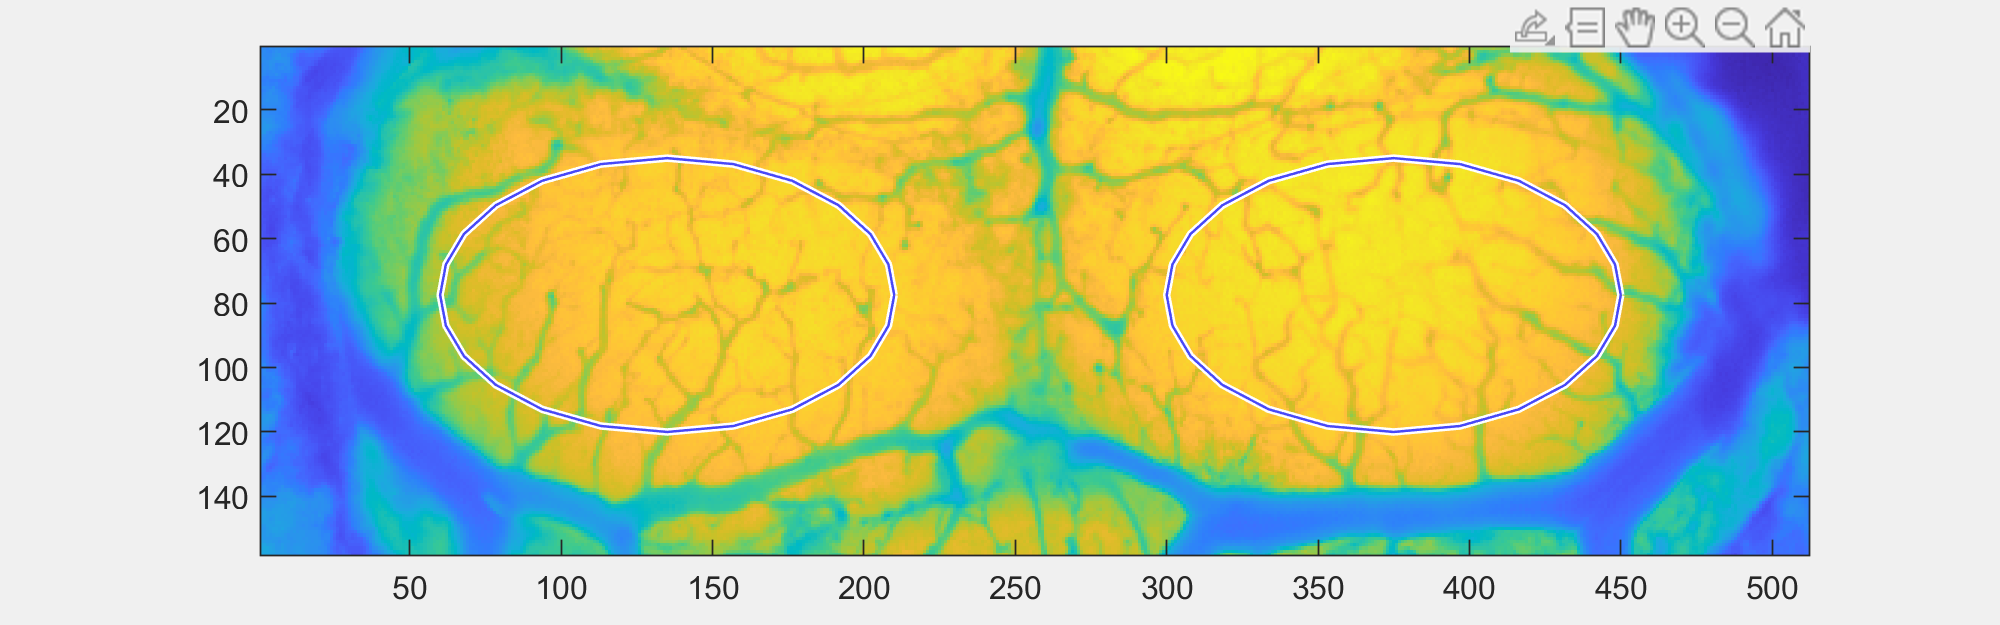

[LICmask, RICmask, ctxmask] = getROImasks(X);

LICsignal = dFoF.*LICmask;
LICsignal(LICsignal == 0) = NaN;
LICsignal = squeeze(mean(mean(LICsignal,2,'omitnan'),'omitnan'));

RICsignal = dFoF.*RICmask;
RICsignal(RICsignal == 0) = NaN;
RICsignal = squeeze(mean(mean(RICsignal,2,'omitnan'),'omitnan'));

ctxsignal = dFoF.*ctxmask;
ctxsignal(ctxsignal == 0) = NaN;
ctxsignal = squeeze(mean(mean(ctxsignal,2,'omitnan'),'omitnan'));

LICint = double(Fo).*LICmask;
LICint(LICint == 0) = NaN;
LICint = mean(mean(LICint,2,'omitnan'),'omitnan');
RICint = double(Fo).*RICmask;
RICint(RICint == 0) = NaN;
RICint = mean(mean(RICint,2,'omitnan'),'omitnan');

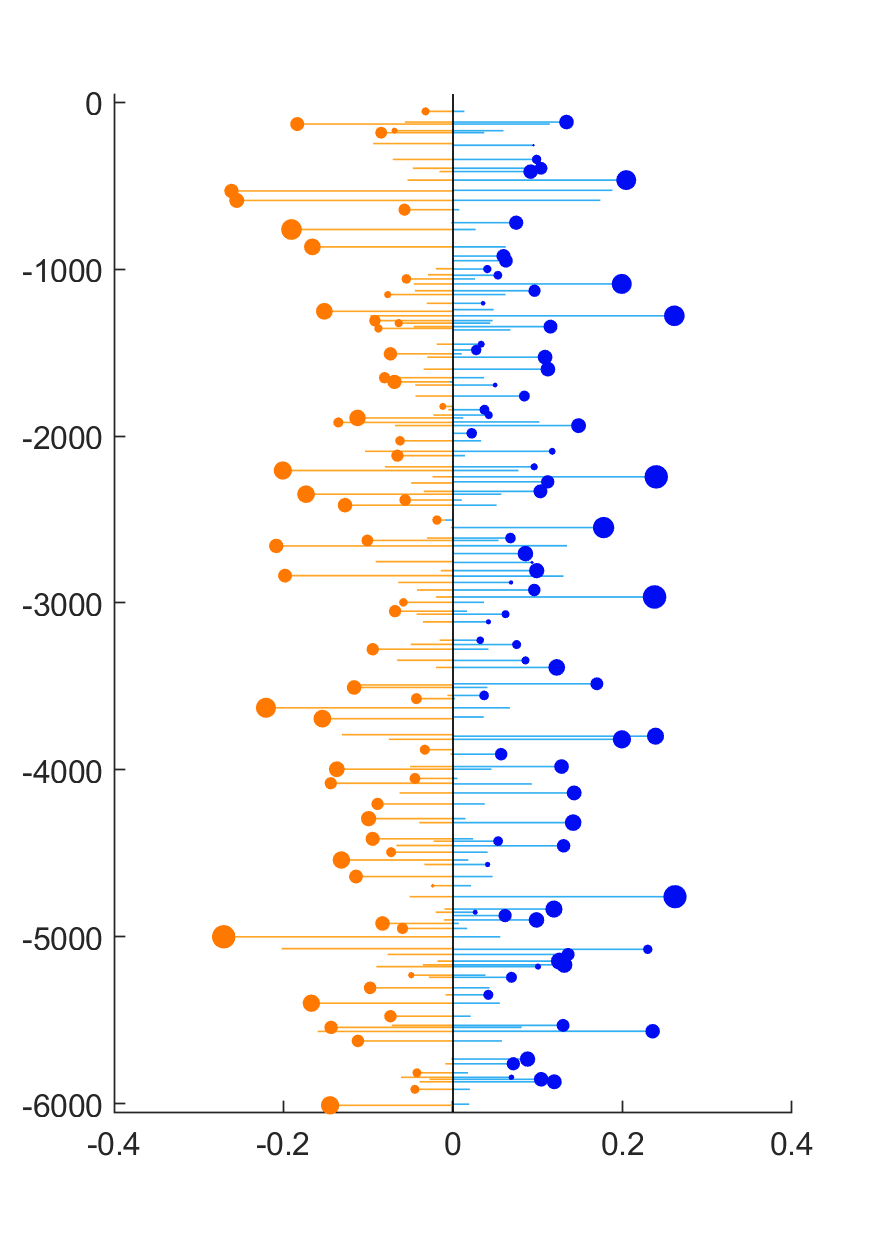

h1 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


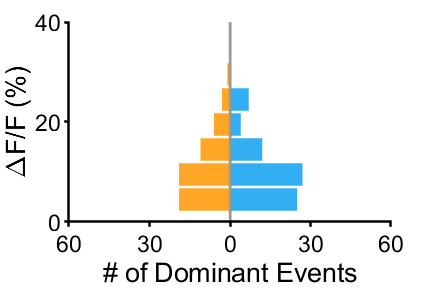

Rdom = 75

tempPkData = 	1.0e+03 *

    0.0540    0.0000    0.0540    0.0000    0.0000    0.0020    0.0010
    0.1300    0.0002    0.1300    0.0001    0.0001    0.0020    0.0010
    0.1700    0.0001    0.1700    0.0001    0.0000    0.0030    0.0010
    0.1820    0.0001    0.1820    0.0000    0.0000    0.0020    0.0010
    0.5310    0.0003    0.5270    0.0002    0.0001    0.0010    0.0010
    0.5880    0.0003    0.5870    0.0002    0.0001    0.0010    0.0010
    0.6430    0.0001    0.6430    0.0000    0.0000    0.0020    0.0010
    0.7620    0.0002    0.7620    0.0000    0.0002    0.0020    0.0010
    0.8660    0.0002    0.8660    0.0001    0.0001    0.0020    0.0010
    1.0580    0.0001    1.0580    0.0000    0.0000    0.0020    0.0010


LIC: 75 peaks total, 23 corresponding RIC peaks.
RIC: 84 peaks total, 23 corresponding LIC peaks.
Mean RIC amplitude: 0.078412
Mean LIC amplitude: 0.07177
D:\Projects and Analysis\Papers\Development\Fig11_TAB_edits\Data\a9 KO example\\Experiment-0293\ICinfo16_dFoF


foldername = regexp(fname,'Experiment-\d*','match');
foldername = foldername{1};
mkdir(dname,foldername);

[stats, pkData] = P2ry1_findICpeaksdFoF(double([LICsignal RICsignal ctxsignal]),[dname '\' foldername],'dFoF',1);

save([dname '\' foldername '\dFoFvars.mat'], 'LICint', 'RICint', 'Fo');
writeTif(single(mean(img-Fo,3)),[dname '\' foldername '\meantif.tif'],32);

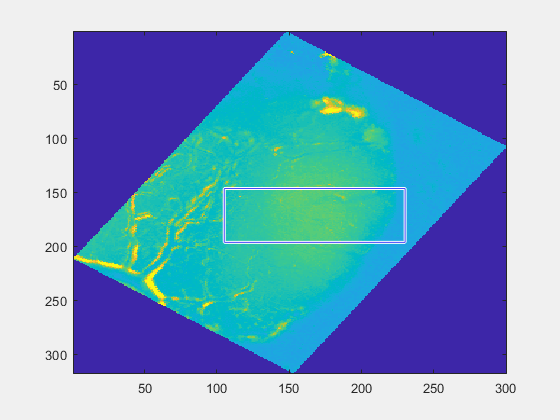

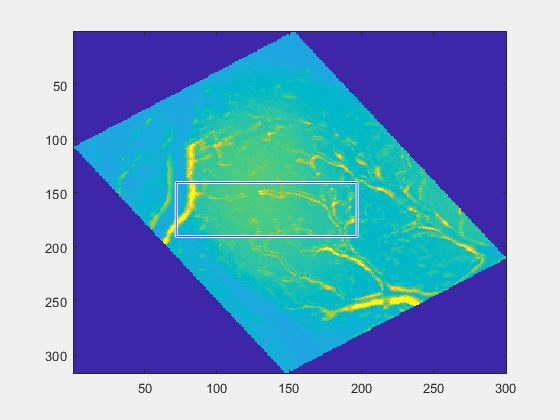

 [LICmov, RICmov] = ROIselection(dFoF);

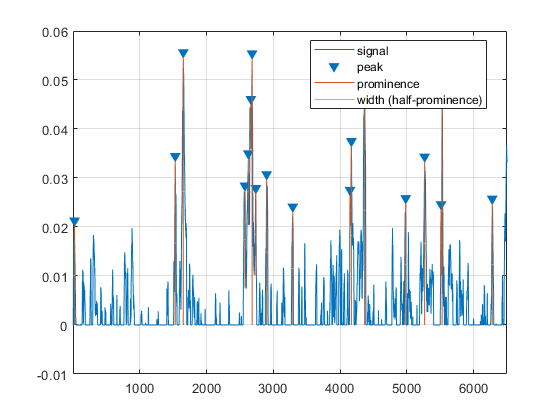

 meanLIC = squeeze(mean(LICmov,1));
 percentLIC = prctile(meanLIC,30,2);
 meanRIC = squeeze(mean(RICmov,1));
 percentRIC = prctile(meanRIC,30,2);

% %%remove background transients from signal
top = dFoF(5:20,10:500,:); %picks area at top of image, middle to account for registration
top = squeeze(mean(mean(top),2));
mid = dFoF(60:80,10:500,:);
mid = squeeze(mean(mean(mid),2));
diff = top - mid;
diff(diff < -0) = 0;
[pks,locs,w]=findpeaks(double(diff),'MinPeakHeight',0.02,'WidthReference','halfprom','MinPeakWidth',7,'Annotate','extents');
figure;
findpeaks(double(diff),'MinPeakHeight',0.02,'WidthReference','halfprom','MinPeakWidth',7,'Annotate','extents');

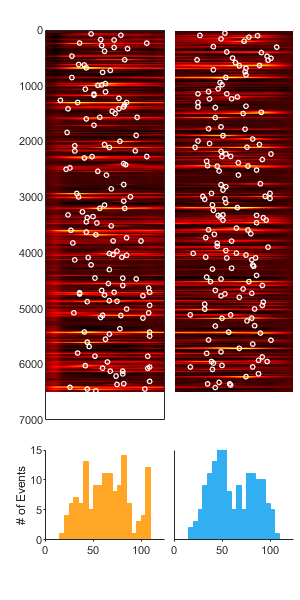

  0×1 empty cell array






flash = zeros(size(top));
for i=1:size(w,1)
    ww = floor(w(i));
    wloc = locs(i);
    left = wloc-ww-2;
    right = wloc+ww+2;
    if left < 1
        left = 1;
    end
    if right > t
        right = t;
    end
    flash(left:right) = 1;
end

[m,n] = size(meanLIC(:,find(flash)));
percentLIC = repmat(percentLIC,1,n);
percentLIC = imnoise(percentLIC,'gaussian',0,.0001);
percentLIC = imgaussfilt(percentLIC);
meanLIC(:,find(flash)) = percentLIC;
[m,n] = size(meanRIC(:,find(flash)));
percentRIC = repmat(percentRIC,1,n);
percentRIC = imnoise(percentRIC,'gaussian',0,.0001);
percentRIC = imgaussfilt(percentRIC);
meanRIC(:,find(flash)) = percentRIC;
% 
smLIC = double(imgaussfilt(meanLIC,3));
smRIC = double(imgaussfilt(meanRIC,3));

%LIC & RIC
[peaksBinaryL] = getPeaks_dFoF(smLIC,0,0.02);
[peaksBinaryR] = getPeaks_dFoF(smRIC,1,0.02);

[peakStat, eventStats] = P2ry1_peakStats_dFoF(smLIC, peaksBinaryL, smRIC, peaksBinaryR);
plotTimeSeries_dFoF(smLIC, smRIC, peaksBinaryL, peaksBinaryR, peakStat);

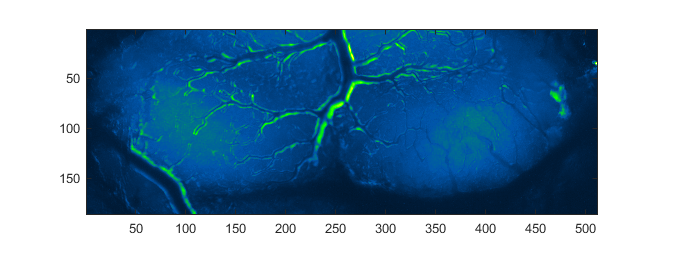


meanTif = mean(X-uint16(Fo),3);
figure; imagesc(meanTif); truesize; colormap(gfb); caxis([0 400])

savefile = 'ICmovs_peaks_dFoF_remflash.mat';
save([dname '\' savefile],'smLIC','smRIC','peaksBinaryR','peaksBinaryL','meanTif'); 
[dname '\' savefile]

ans = 'C:\alpha9 GOF widefield\KO\1649 KO\\ICmovs_peaks_dFoF_remflash.mat'